# Solve Stiff ODE

An example of a stiff system of equations is the van der Pol equations in relaxation oscillation. The cycle has regions where the solution components change slowly and the problem is quite stiff, alternating with regions of very sharp change where it is not stiff.

The van der Pol equation is


$$\frac{d^2y}{dt^2} = \mu\left(1-y^2\right)\frac{dy}{dt} - y$$


which needs two initial conditions, $y\left(0\right)=y_0 ,\mathrm{y'}\left(0\right)=v_0$. The system of equations can be written with the convention `y = [y(1); y(2)]`

Solving this system using `ode45` with the default relative and absolute error tolerances (`1e-3` and `1e-6`, respectively) is extremely slow, requiring several minutes to solve and plot the solution. `ode45` requires millions of time steps to complete the integration, due to the areas of stiffness where it struggles to meet the tolerances. 

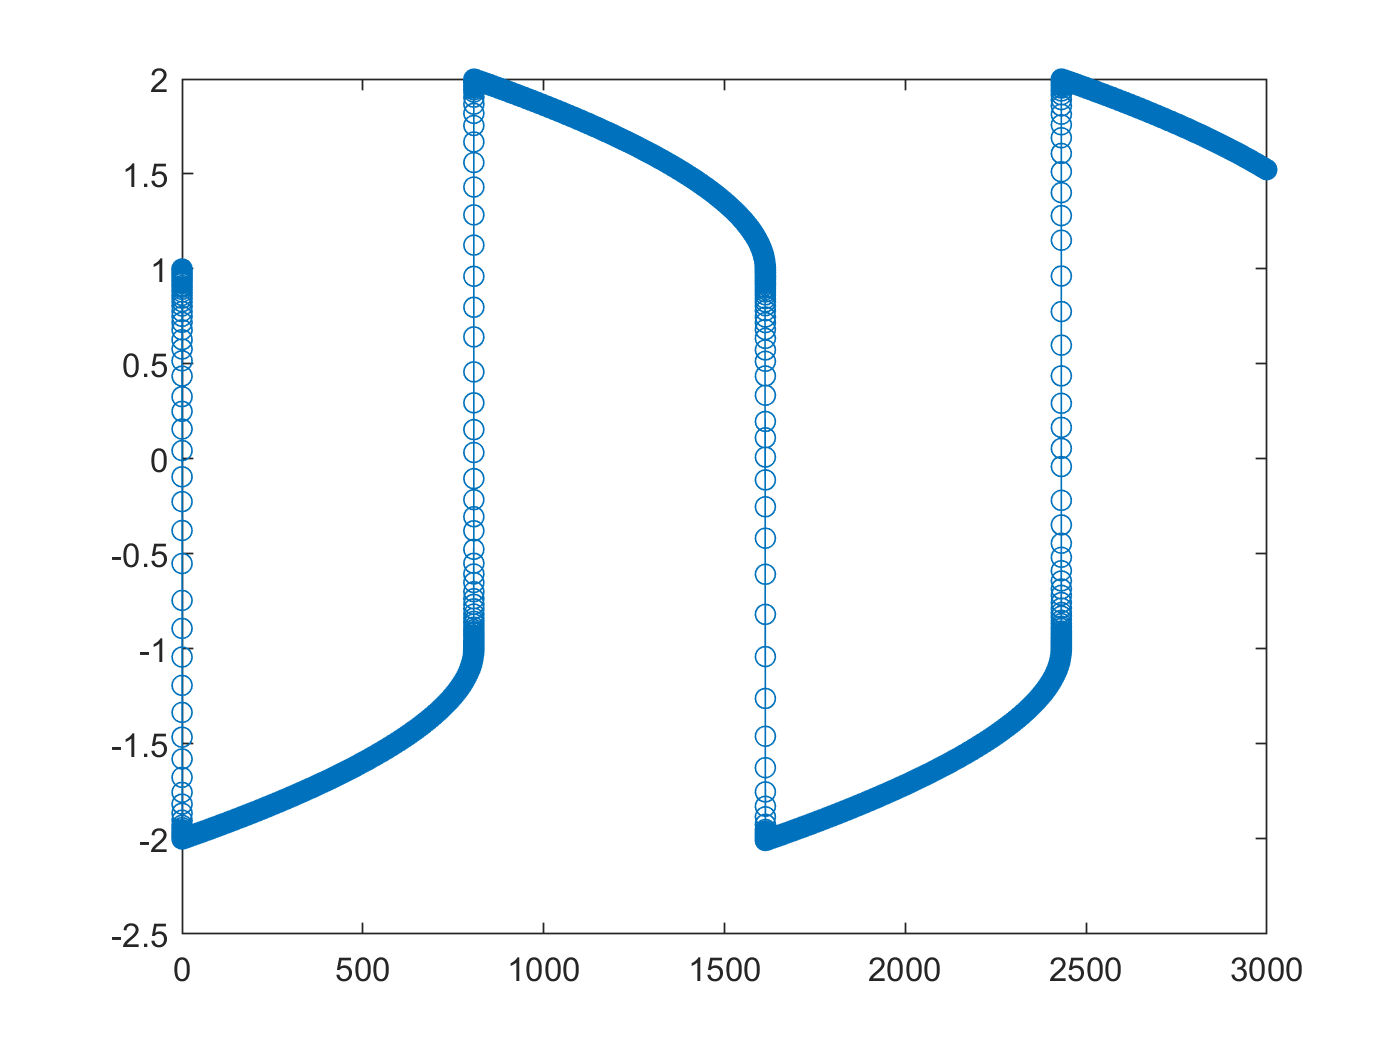

vanderpol = @(t,y) [y(2); 1000*(1-y(1)^2)*y(2)-y(1)];
[t,y] = ode45(vanderpol,[0 3000],[1 0]);
plot(t,y(:,1),'-o')

length(y)

ans =     6758557.00

Solve the stiff system using the `ode15s` solver, and then plot the first column of the solution `y` against the time points `t`. The `ode15s` solver passes through stiff areas with far fewer steps than `ode45`.

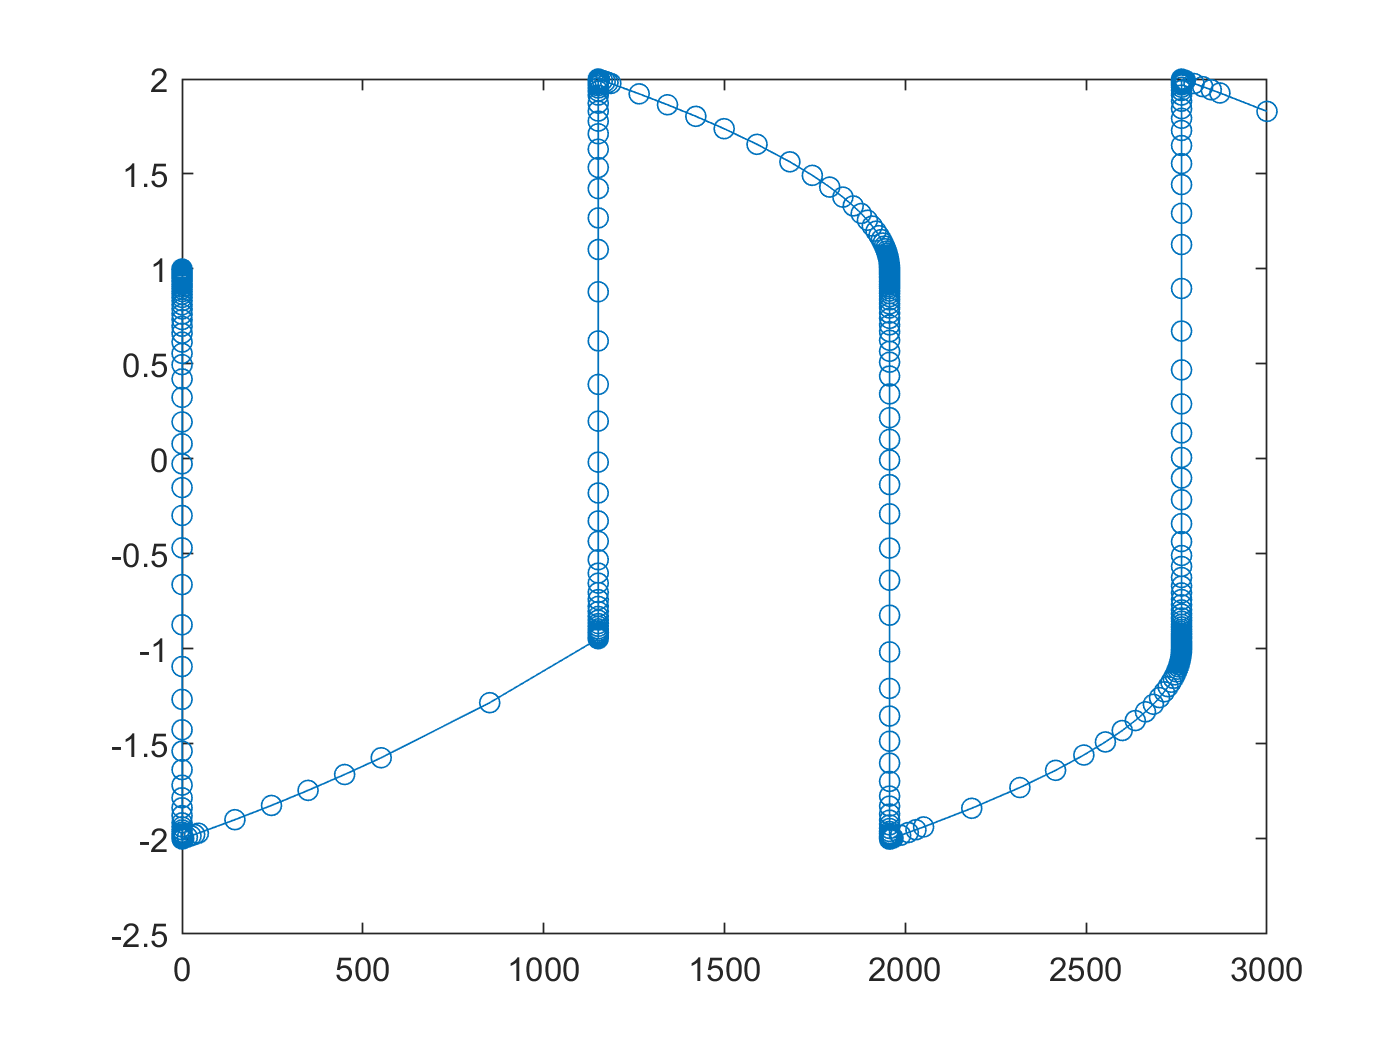

[ts,ys] = ode15s(vanderpol,[0 3000],[1 0]);
plot(ts,ys(:,1),'-o')

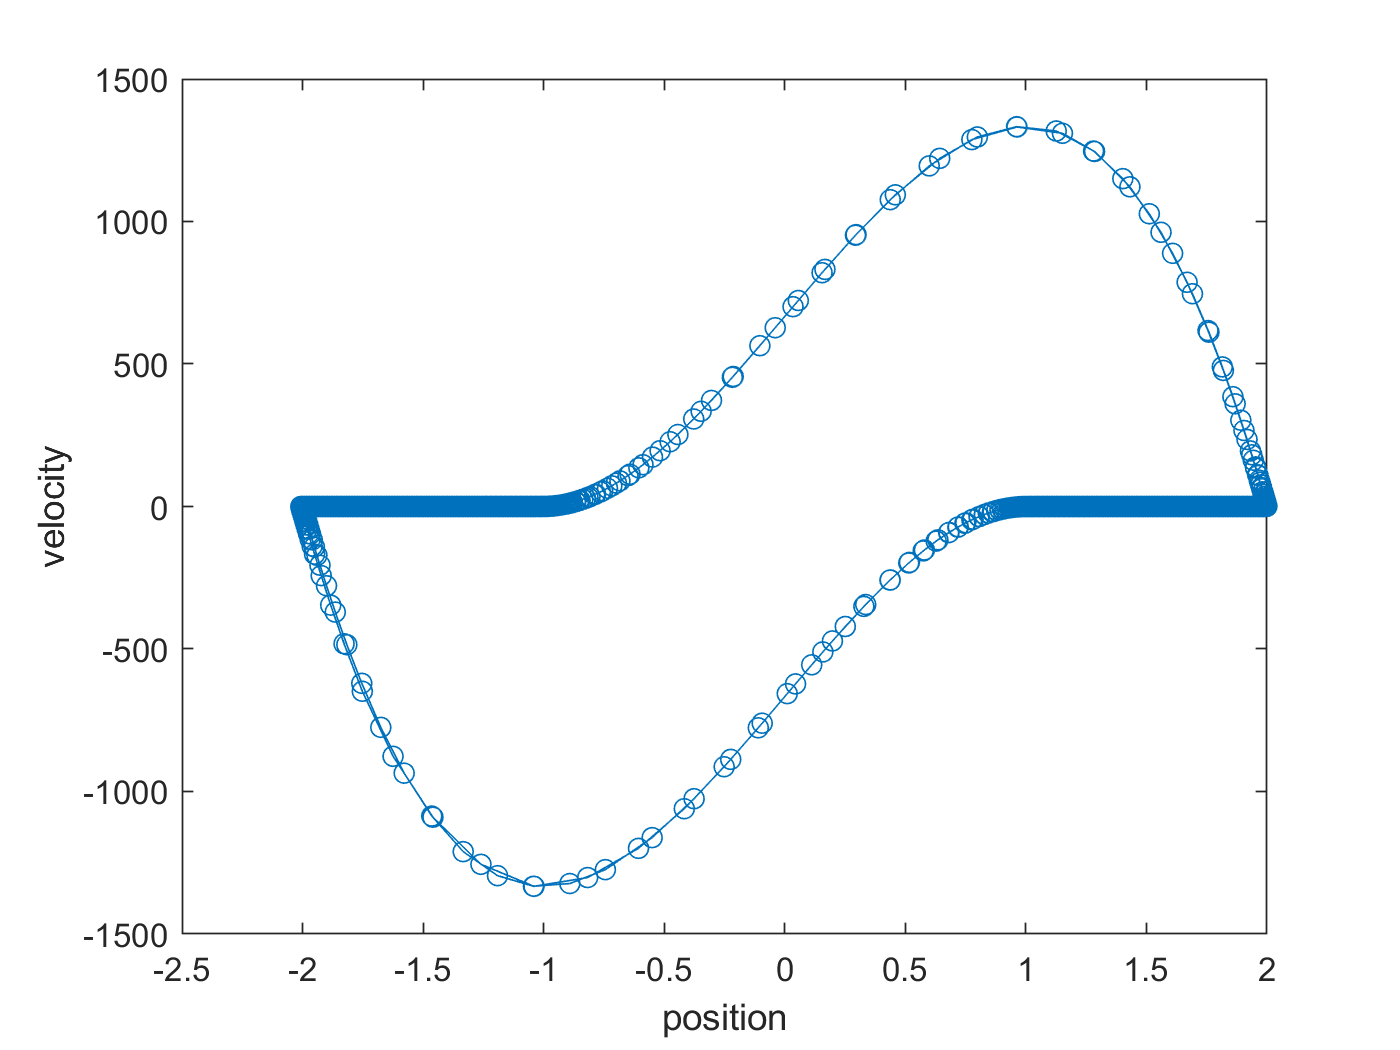

plot(y(:,1),y(:,2),'o-')
xlabel('position')
ylabel('velocity')

length(ys)

ans =         716.00